% Live Script sulla Lastra piana in reggime supersonico:
% prima sezione permette di scecliere un numero di mach e vedere andamento
% di Cl, Cd ed efficienza risolta con la tecnica Shock - Expansion
clear
clc

gamma = 1.4;
M = 2;              % Slider del numero di Mach di volo
p = 1e5;
T = 280;
c = 1;
alpha1 = theta_max(M,gamma) - 0.01;        % per evitare urti curvi si limita l'angolo d'attacco ad
                                           % uno leggermente inferiore del
                                           % massimo
if alpha1 > 20 *pi/180                     
    alpha1 = 20 *pi/180;
end

alpha = linspace(0.001,alpha1,100);

[L,D,Cd,Cl] = lastra_supersonica(alpha,p,T,M,gamma,c);

Grafico che mostra l'andamento del coefficiente di lift in funzione dell'angolo di attacco

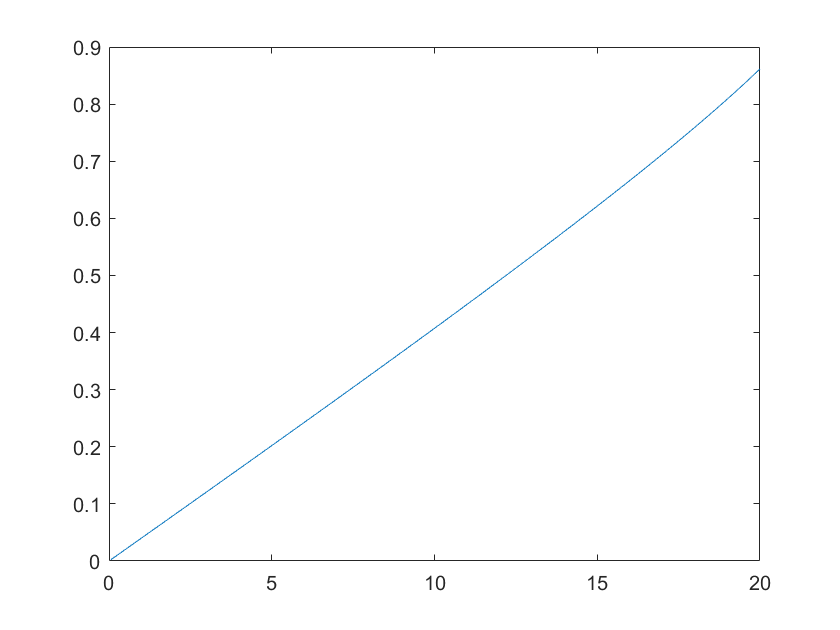

plot(alpha.*180./pi,Cl) % asse x angolo d'attacco in gradi; asse y Cl

Grafico che mostra l'andamento del coefficiente di drag in funzione dell'angolo di attacco

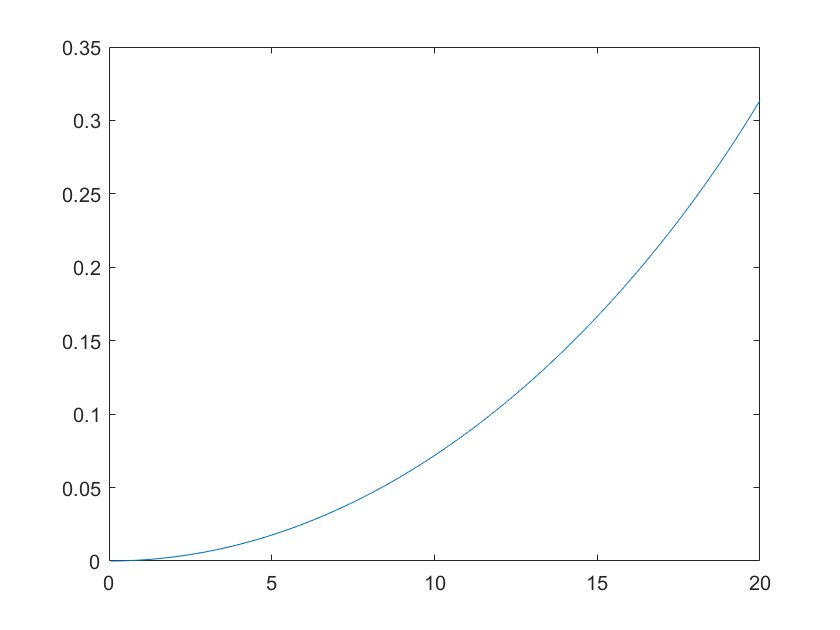

plot(alpha.*180./pi,Cd)     % asse x angolo d'attacco in gradi asse y Cd

Grafico che mostra l'andamento dell'efficienza aerodinamica in funzione dell'angolo di attacco

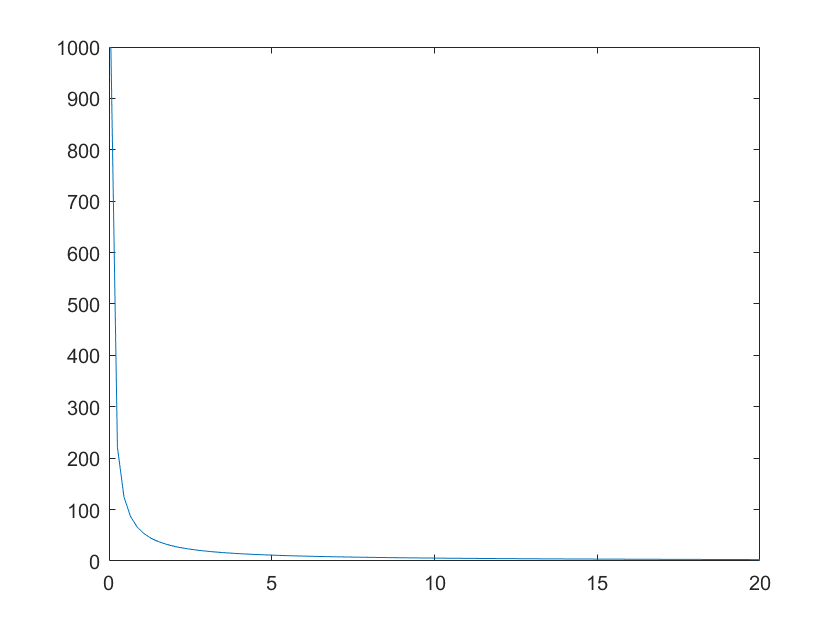

plot(alpha.*180./pi,Cl./Cd)     % asse x angolo d'attacco in  gradi; asse y Cl/Cd

% Seconda sezione si mostra l'andamento del Cl, ad un deteminato angolo di
% attacco, in funzione del numero di Mach
clear
clc


gamma = 1.4;
M = linspace(1.5,5,100);
p = 1e5;
T = 280;
c = 1;
alpha = 10.3;    % silder per scegliere l'angolo di attacco
Cl_v = [];
Cd_v = [];

for i = [1:length(M)]
    
    [L,D,Cd,Cl] = lastra_supersonica(alpha*pi/180,p,T,M(i),gamma,c);
    Cl_v(i) = Cl;
    Cd_v(i) = Cd;
end


Grafico che mostra l'andamento del coefficiente di lift in funzione del numero di Mach

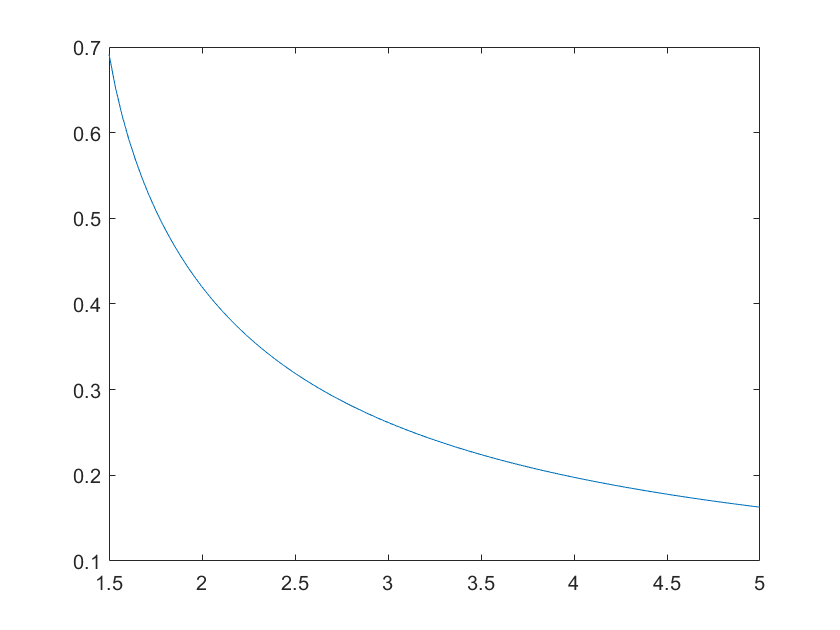

plot(M,Cl_v)   % asse x numero di Mach; asse y Cl

Grafico che mostra l'andamento del coefficiente di drag in funzione del numero di Mach

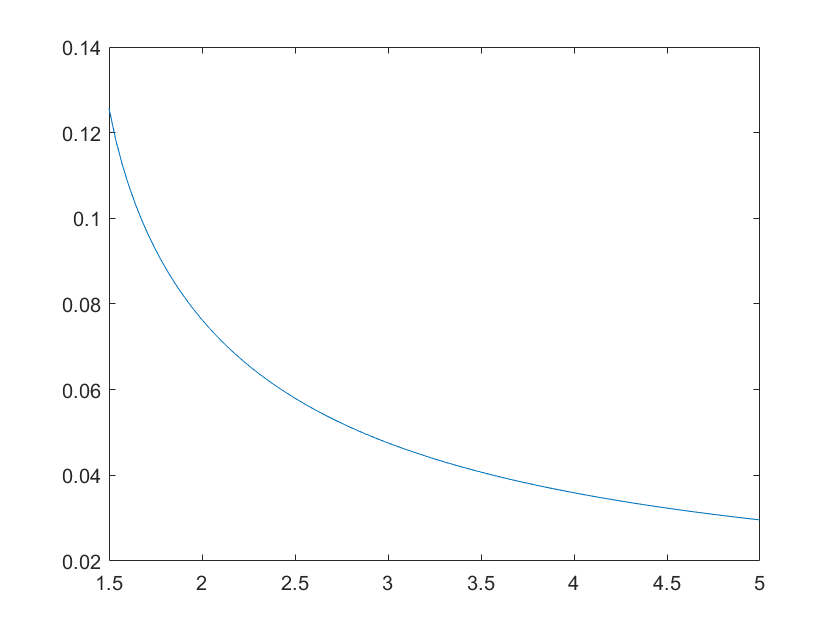

plot(M,Cd_v)     % asse x numero di Mach; asse y Cd

Grafico che mostra l'andamento dell'efficienza aerodinamica in funzione del numero di Mach

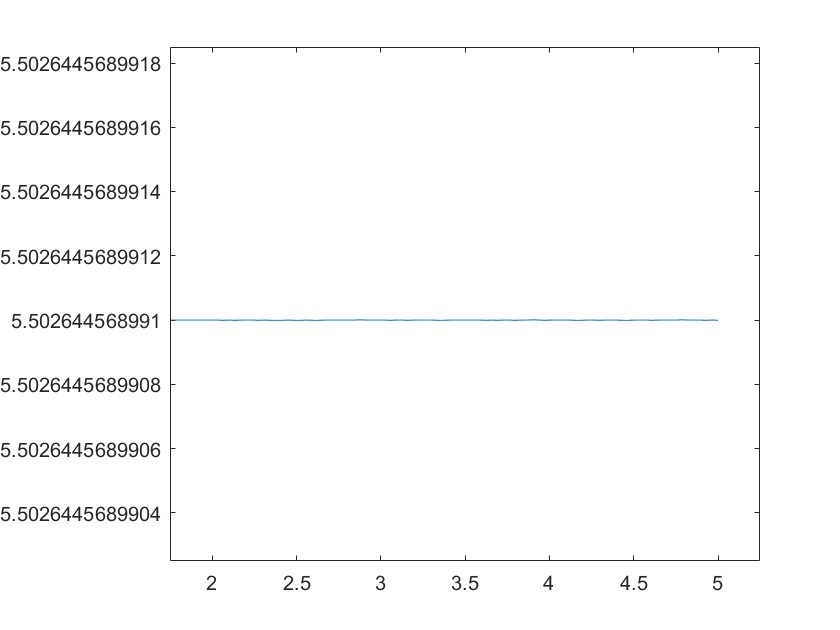

plot(M,Cl_v./Cd_v) % il rapporto Cl/Cd non dipende dal nummero di Mach, ma solo dal'angolo d'attacco